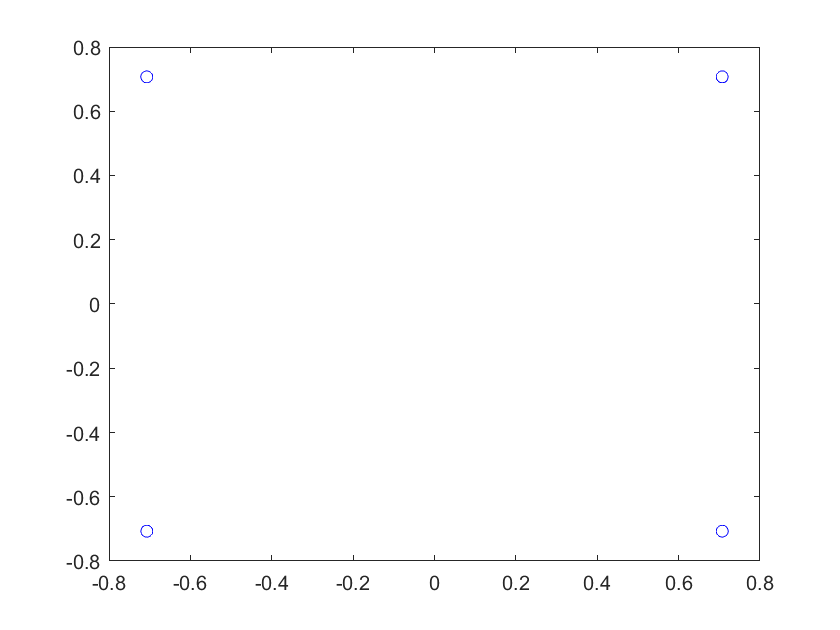

% OFDM系统自发自收

% Turbo编码->QPSK->插导频->OFDM调制->插CP->同步头->发送
clc;
clear;

fs = 20e6;

% lteTurboEncode特定数量
data_num = 2016;
data = randi([0,1],1,data_num);

% (6060,1)
turbo_mod = lteTurboEncode(data).';

symbol = lteSymbolModulate(turbo_mod,'QPSK');

col = 101;
row = 30;
block_sym = reshape(symbol,col,row);
figure(7);
plot(block_sym(:).','bo');

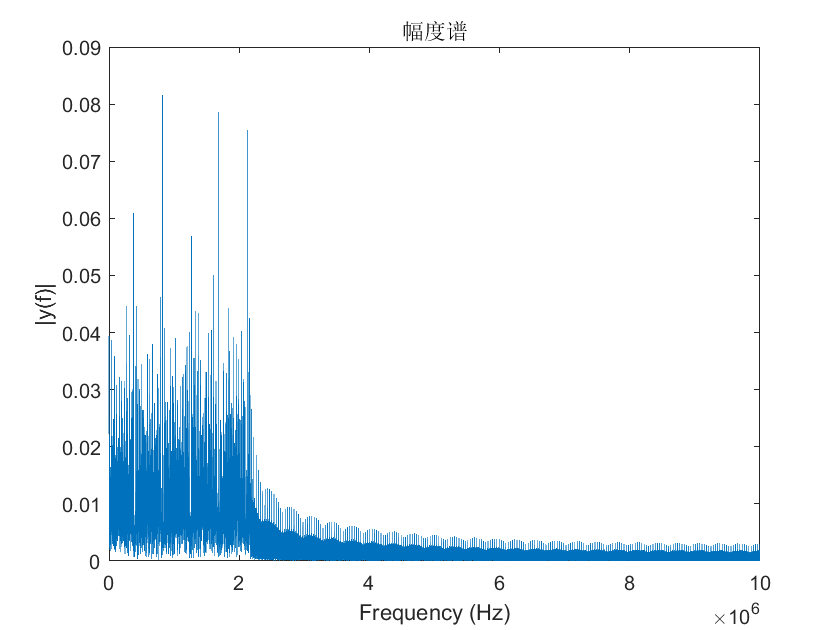



% 插入导频
block_interval = 3;
comb_interval = 10;
[inserted_sym,data_col_loc,data_row_loc,block_pilot_loc,comb_pilot_loc]= Insert_pilot(block_sym,block_interval,comb_interval);

% OFDM
ifft_num = 512;
OFDM_sym = OFDM_modulate(inserted_sym,ifft_num);

% 插入循环前缀
cp_length = 72;
cp_sym = Insert_cp(OFDM_sym,cp_length);

tx_data = cp_sym(:).';
figure(1);
DrawFFT(tx_data,fs);

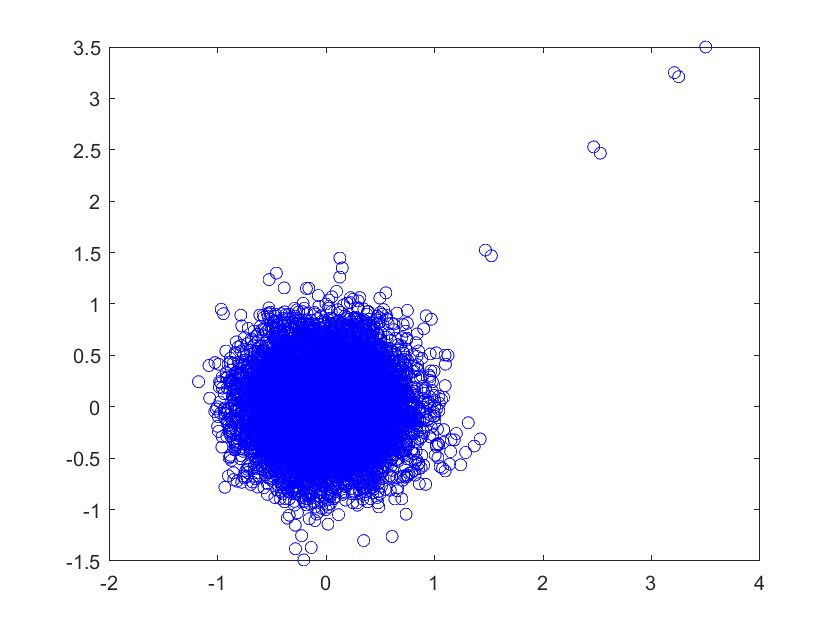

% turbo_demod = lteTurboDecode(turbo_mod).';

% 插入同步序列
N=32*4;
sk_len = 64;
[zc_added_sym,sk] = Insert_zcseq(tx_data);
figure(8);
plot(zc_added_sym,'bo');


txPluto = sdrtx('Pluto','RadioID','usb:0','CenterFrequency',4e8, ...
    'BasebandSampleRate',fs,'ChannelMapping',1,'Gain',0);


rxPluto = sdrrx('Pluto','RadioID','usb:0','CenterFrequency',4e8, ...
    'BasebandSampleRate',fs,'ChannelMapping',1,'OutputDataType','double','Gain',30,'SamplesPerFrame',length(zc_added_sym)*4); 

i = 1000;

% 发送
modSignal = zc_added_sym.';
txPluto.transmitRepeat(modSignal);

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


## Establishing connection to hardware. This process can take several seconds.


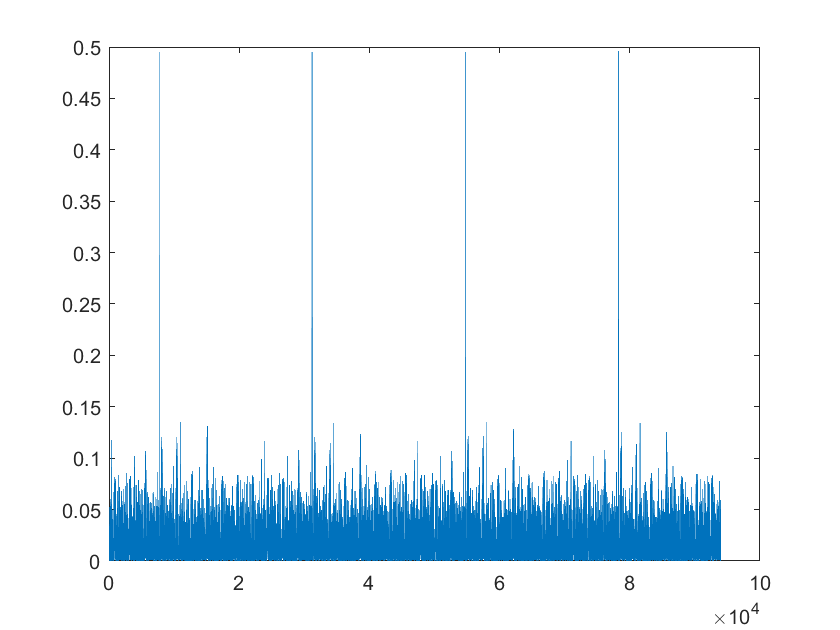

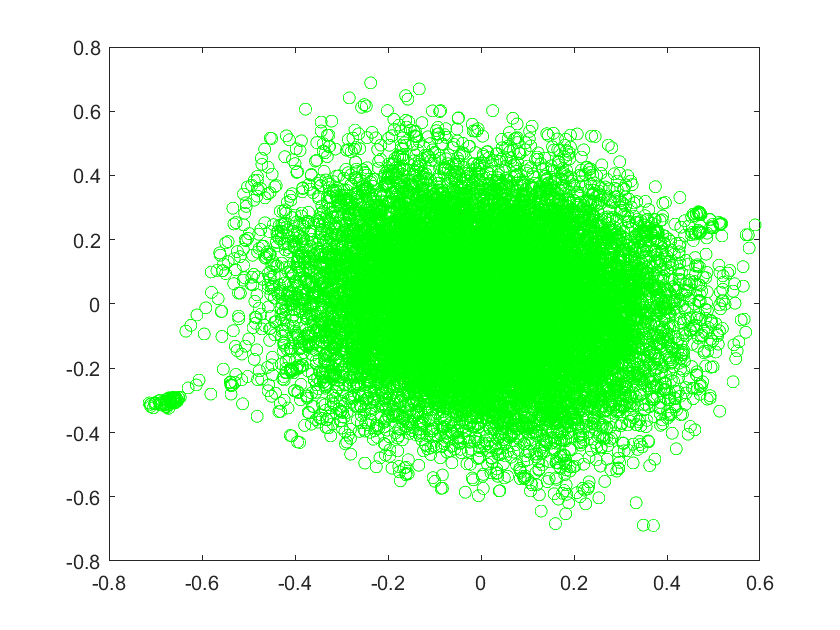

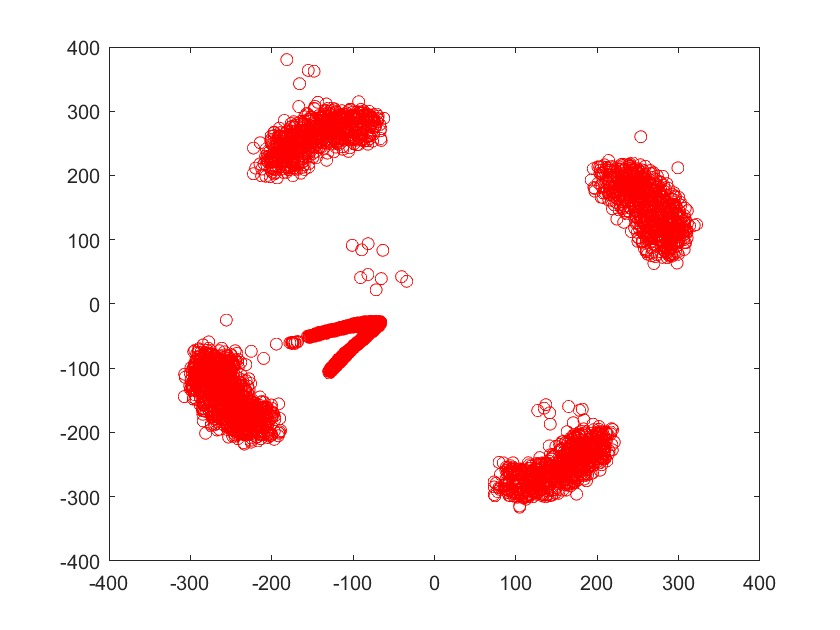

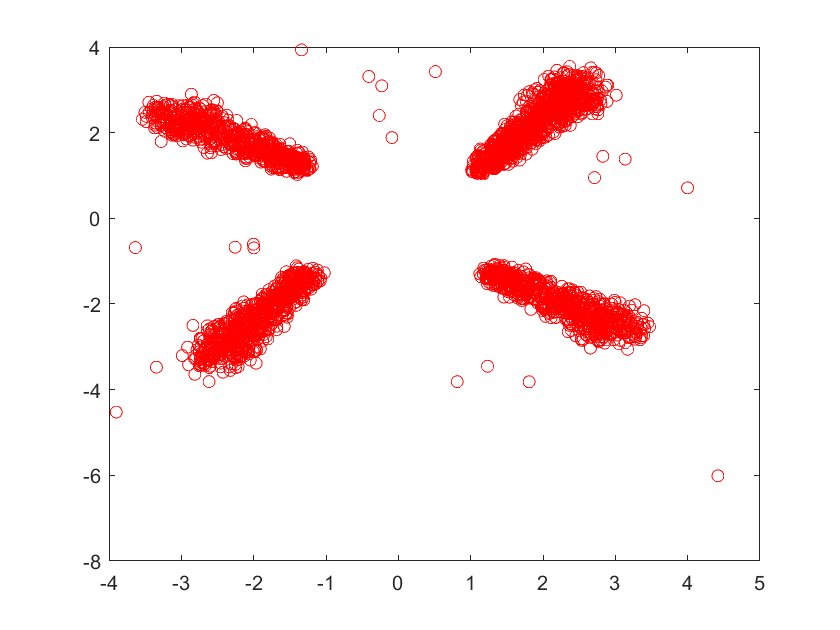

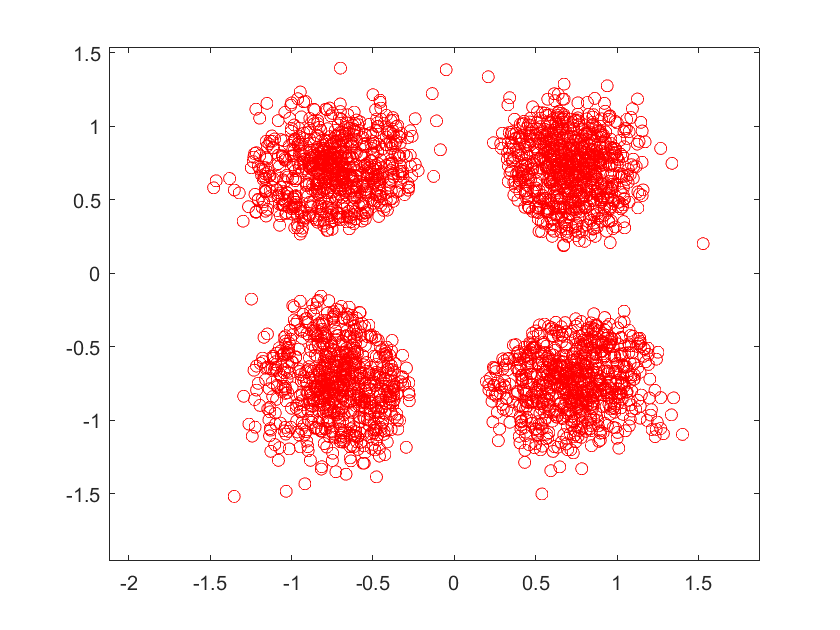

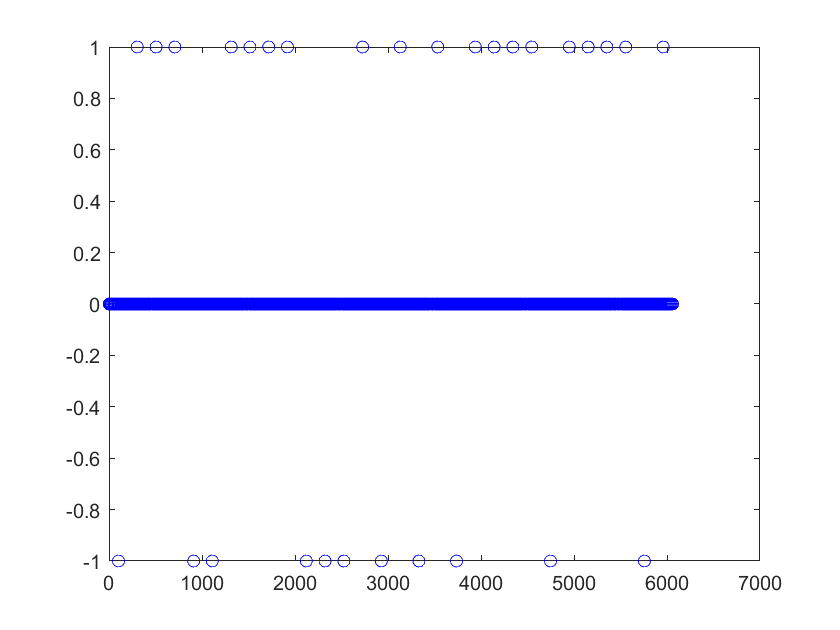

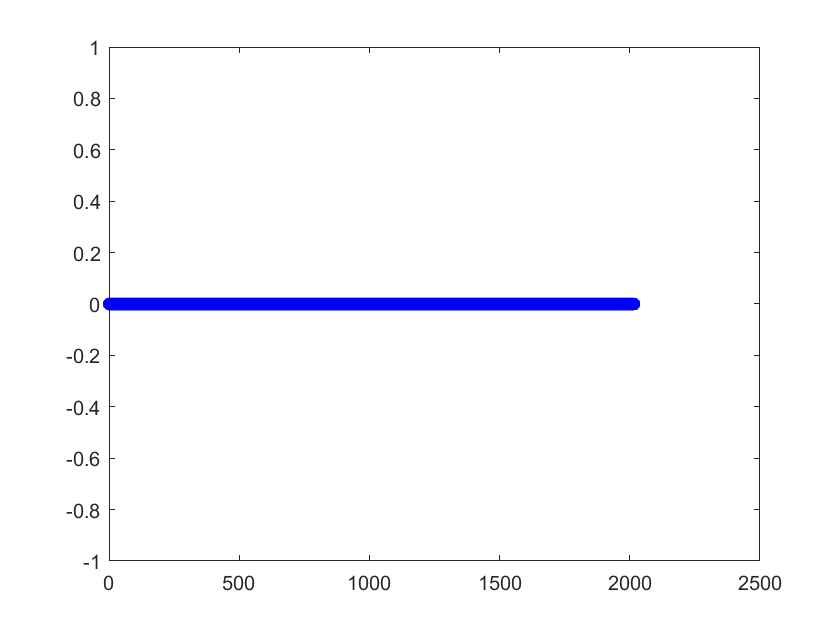


while(i>0)


    % 接收
    [rx_data,datavalid,overflow] = rxPluto();
    rx_data = rx_data.';

%     rx_data = [zc_added_sym zc_added_sym];
    
    % 同步 
    % 算法采用这个 [1]刘彬,罗志年,彭疆.改进CAZAC序列的OFDM时频同步算法[J].计算机工程与应用,2017,53(14):76-79+98.
    
    [M,p1] = STO(rx_data,N,sk);
    figure(1);
    plot(M);
    
    STO_loc = find(M > 0.25);
    if(length(STO_loc) > 1)


        start = STO_loc(1);
        
        % 频偏纠正
        CFO_seq = CFO(rx_data,start,N,p1,ifft_num);
        rx_seq = CFO_seq(start+N:start+N+length(tx_data)-1);
        
        figure(2);
        plot(rx_seq,'go');
        
        % 去掉循环前缀
        del_cp_sym = Del_cp(rx_seq,ifft_num,cp_length);
        
        % OFDM解调
        fft_num = ifft_num;
        carrier_num = size(inserted_sym,1);
        de_OFDM_sym = OFDM_demodulate(del_cp_sym,fft_num,carrier_num);
        
        figure(9);
        plot(de_OFDM_sym,'ro');
        
        % 分离块状导频
        block_pilot = de_OFDM_sym(:,block_pilot_loc);
        data_mat = de_OFDM_sym(:,data_row_loc);
        
        % 信道估计与均衡
        pilot1 = (ones(size(block_pilot,1),size(block_pilot,2)) + ones(size(block_pilot,1),size(block_pilot,2)).*1i)./sqrt(2);
        % LS信道估计
        H = LS_estimate(block_pilot,pilot1,block_interval+1);
        data_balanced = data_mat./H;    %均衡
        
        figure(10);
        plot(data_balanced,'ro');
        
        % 相位纠正
        comb_pilot = data_balanced(comb_pilot_loc,:);
        data_mat = data_balanced(data_col_loc,:);
        pilot2 = (ones(size(comb_pilot,1),size(comb_pilot,2)) + ones(size(comb_pilot,1),size(comb_pilot,2)).*1i)./sqrt(2);
        h_fft=comb_pilot.*conj(pilot2);
        h_time=ifft(h_fft);
        h_fft=fft(h_time,size(data_mat,1));
        data_balanced=data_mat./h_fft;
        
        data_sym = data_balanced(:).';
        
        figure(3);
        plot(real(data_sym),imag(data_sym),'ro');
        % QPSK解调
        QPSK_dem_data = lteSymbolDemodulate(data_sym,'QPSK','Soft');
        % 量化
        quant_data = int8(quantiz(QPSK_dem_data,0,[0,1]));
        % 解turbo码
        data_dem = lteTurboDecode(QPSK_dem_data).';
        
        figure(20);
        plot(quant_data.' - turbo_mod,'bo');  
        figure(21);
        plot(data - double(data_dem),'bo');  
        
        
        break;
    else
        
    end

   
end